# Part 8: 制御器の設計と自作の方法

電力系統の負荷はいつも変わり、事故や解列も予告なしに起こります。発電機だけでは、これらに対して電圧や回転の速さを一定に保てません。それを行うのが制御器です。この Part では、発電機 1 台を見るローカル制御器（AVR・PSS・ガバナ）、周波数を戻す AGC、モデルからゲインを選ぶ LQR、部分のモデルだけで後付けする Retrofit 制御を、式と GUILDA の計算で順に確かめます。最後に、どの制御器も「観測 → 計算 → 入力」の同じ形をしていることを、GUILDA のクラスの中で確かめます。

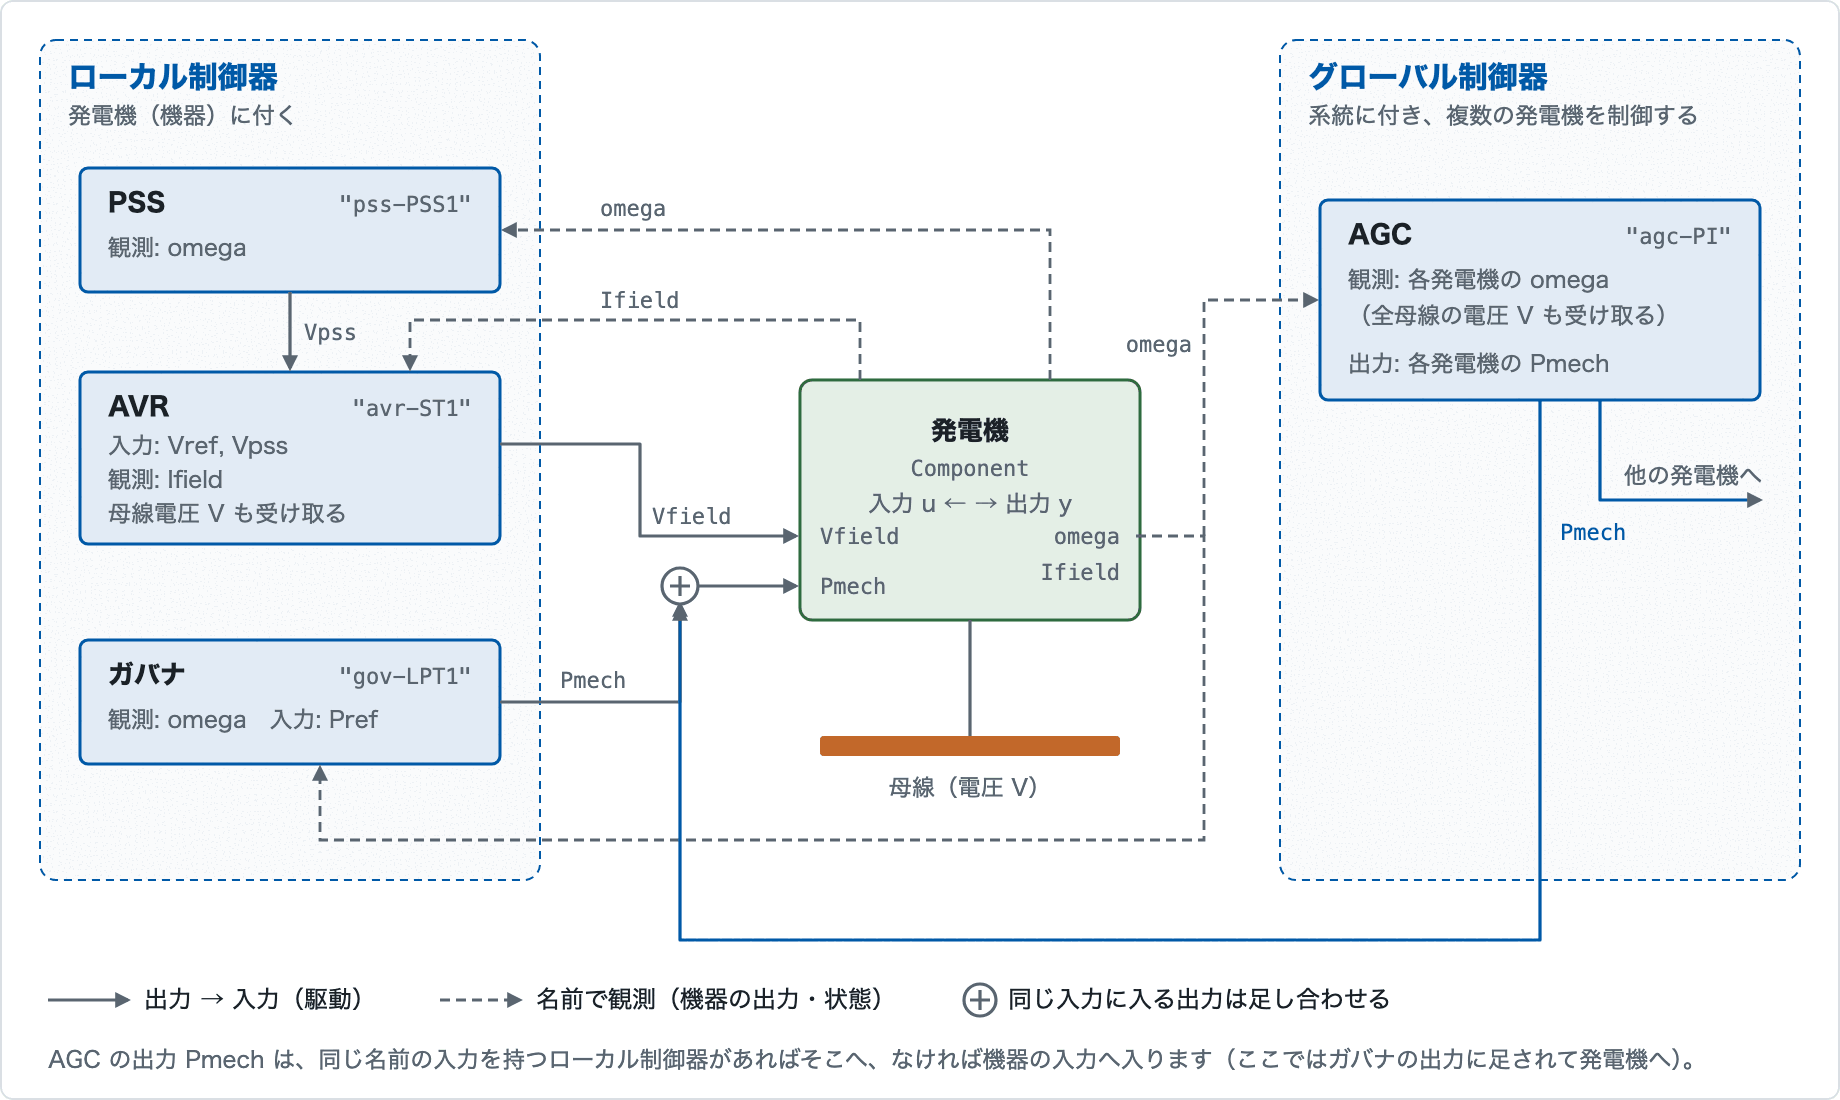

制御器の付き方と信号の向きです。ローカル制御器は発電機に付き（PSS → AVR → `Vfield`、ガバナ → `Pmech`）、グローバル制御器（AGC）は系統に付いて各発電機の `omega` を名前で観測し、`Pmech` に出力を足します。図は一例です（図の Key は、この Part の各節で使う Key と違うことがあります）。

**この Part で分かること**

- フィードバックの基本と、制御器が固有値を動かすという見方

- 速い AVR が揺れの減衰を弱めることがある理由と、PSS が制動トルクをつくる仕組み

- 周波数制御の階層：ガバナの垂下特性でずれが残る理由と、AGC の積分がずれを 0 に戻す理由

- LQR の評価関数とリッカチ方程式、Retrofit 制御の補正器と誤差の式

- 制御器を自作するときの「観測 → 計算 → 入力」が、GUILDA のクラスのどこに当たるか

知識ページ: [Part 8: 制御器の設計と自作の方法](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part8-controller-design.html","-browser")) （クリックするとブラウザで開きます）。知識ページの図は、このライブスクリプトの中のコードで描いています。

**注意:** GUILDA のフォルダがパスに入っている（`GUILDA.addpath` を実行済みの）状態で実行します。LQR と Retrofit 制御は Control System Toolbox を使います。全体の実行には 1〜2 分かかります。知識ページの図に合わせて、PSS・周波数制御・Retrofit 制御は IEEE 9 母線系統で、制御器の観察と LQR は IEEE 68 母線系統で確かめます。

図は、知識ページの図と同じ大きさで描きます。図を作るときの設定（白い背景、文字 8 pt）を最初にまとめておきます。

c_fig = {"Color", "w", "Units", "centimeters", "DefaultAxesFontSize", 8, ...
    "DefaultTextFontSize", 8, "DefaultLegendFontSize", 8, "DefaultLegendFontSizeMode", "manual"};

## 1. フィードバックの基本と、発電機の制御器

### フィードバック

制御器は、ある量を測り、目標の値と比べ、その差が小さくなるように発電機の入力を変えます。測った結果を戻して次の動きを決めるので、これをフィードバックといいます。いちばん簡単な比例制御では、目標値を $r$、測った出力を $y$、ゲインを $K$ として、ずれ $e$ と入力 $u$ を次のように計算します。


$$e(t) = r - y(t), \qquad u(t) = K e(t)$$


ゲインが小さいと反応が遅く、ずれが大きく残ります。ゲインが大きいと素早く反応しますが、信号がループを一周するには時間がかかるので、修正が遅れて行き過ぎ、大きすぎるとループそのものが大きくなっていく振動を起こします。系統の線形モデルの言葉では、制御器は固有値を動かします。振動する固有値の対 $\sigma \pm j\omega$ の 1 つ 1 つが揺れの型で、$\sigma \lt 0$ なら揺れは収まり、その速さをダンピング比 $\zeta = -\sigma/\sqrt{\sigma^2 + \omega^2}$ が表します。よい制御器は固有値を左へ動かします。

### 発電機のローカル制御器を見る

同梱の IEEE 68 母線系統（発電機 16 台、母線 16 が slack 母線）を読み込みます。どの発電機にも AVR と PSS が付いています。母線 9 の発電機を取り出し、`disp_tree` で、どの制御器がどこに付いているかを表示します。

net68 = network.IEEE68bus(LocalController=true);
[~, flag] = net68.initialize()

flag = 1

gen = net68.get_element("B009SG1");
gen.disp_tree


 B009SG1 @component.generator.one_axis
   ┣━━ B009SG1CA1 @controller.avr.AVR_ST1
   ┃     ┗━━ B009SG1CP2 @controller.pss.PSS1
   ┗━━ B009SG1CG1 @controller.governor.Static




発電機の下に AVR（`CA1`）とガバナ（`CG1`）、AVR の下に PSS（`CP2`）が付いています。このガバナは既定の `gov-static` で、機械入力を平衡点の値のまま出し続け、周波数には反応しません。`get_element_table` で、発電機とその制御器の Key・役割・状態・入力（観測する信号）・出力（動かす入力）を並べます。

tab_el = net68.get_element_table();
tab_el(startsWith(tab_el.Tag, "B009SG1"), ["Key", "Role", "State", "Input", "Output"])

ans = 4×5 table
                      Key            Role             State                  Input                Output     
                  ____________    __________    __________________    ____________________    _______________

    B009SG1       "gen-1axis"     ""            "delta, omega, Eq"    "Pmech, Vfield"         "omega, Ifield"
    B009SG1CA1    "avr-ST1"       "avr"         "Vtr, Vap, Vst"       "Vref, Vpss, Ifield"    "Vfield"       
    B009SG1CP2    "pss-PSS1"      "pss"         "xiWS, xi1, xi2"      "omega"                 "Vpss"         
    B009SG1CG1    "gov-static"    "governor"    ""                    "Pmech_ref"             "Pmech"        


発電機には外から変えられる入力が 2 つあります。内部電圧を決める界磁電圧 `Vfield` と、タービンからの機械入力 `Pmech` です。AVR の出力 `Vfield` が発電機の入力 `Vfield` を、PSS の出力 `Vpss` が AVR の入力 `Vpss` を動かします。PSS は発電機の出力 `omega`（回転の速さのずれ）を観測します。AVR は発電機のもう 1 つの出力 `Ifield`（界磁電流）も観測します。これは界磁電流に応じて界磁電圧の上限を下げるリミッタのための入力で、既定の値ではそのリミッタは働かず、応答は変わりません。GUILDA は、このように同じ名前の信号どうしをつなぎます。つながり方は `get_variable_map` の 2 番目の出力で確かめられます。

[~, conn] = gen.get_variable_map();
conn(:, ["Kind", "Source", "Target"])

ans = 7×3 table
        Kind               Source                   Target        
    _____________    ___________________    ______________________

    "local"          "Pmech_B009SG1CG1"     "Pmech_B009SG1"       
    "local"          "Vfield_B009SG1CA1"    "Vfield_B009SG1"      
    "equilibrium"    ""                     "Vref_B009SG1CA1"     
    "local"          "Vpss_B009SG1CP2"      "Vpss_B009SG1CA1"     
    "observe"        "Ifield_B009SG1"       "Ifield_B009SG1CA1"   
    "observe"        "Y_omega_B009SG1"      "omega_B009SG1CP2"    
    "equilibrium"    ""                     "Pmech_ref_B009SG1CG1"


`local` は制御器の出力が親の入力を動かすつながり、`observe` は制御器が発電機の出力を観測するつながりです。

**注意:** IEEE 68 母線系統の AVR（`avr-ST1`）は、出力に ±5 pu のリミッタが付いています（AVR のパラメータの `dynamics` のグループの `Limiter`、`Vap_max`、`Vap_min`。`net68.get_parameter("dynamics", Key="avr-ST1")` で見られます）。平衡点の界磁電圧はこの範囲に入っているので、平衡点と線形化はリミッタに依りません。制御器を付けたり外したりした後は、もう一度 `initialize` してから計算します。

## 2. AVR と PSS：揺れに制動をかける

### 同期化トルクと制動トルク

回転子が平衡点のまわりで小さな角度 $\Delta\delta$ だけ揺れると、発電機の電気的なトルクが変わります。ある 1 つの周波数の揺れについて、その変化は 2 つに分けられます。


$$\Delta T_\mathrm{e} = K_\mathrm{S}\Delta\delta + K_\mathrm{D}\Delta\omega$$


角度と同じ位相の同期化トルク（係数 $K_\mathrm{S}$）はばねのように回転子を引き戻し、速さと同じ位相の制動トルク（係数 $K_\mathrm{D}$）は摩擦のように揺れにブレーキをかけます。揺れが収まるには、両方が正である必要があります。ゲインの高い速い AVR は電圧をしっかり保ち、$K_\mathrm{S}$ を大きくするので大きな事故に強くなります。ところが界磁は遅れて応答するので、$K_\mathrm{D}$ への寄与が負になることがあります（deMello と Concordia の説明）。

PSS はこれを直します。速さの信号の位相をフィルタでずらし、AVR を通してつくるトルクが $\Delta\omega$ と同じ位相、つまり純粋な制動トルクになるようにします。GUILDA の PSS `pss-PSS1` は、$\omega$ の変化だけを通すウォッシュアウトフィルタと、2 段の進み遅れのブロックからなります（$s$ はラプラス変換の変数、出力の上下限は省略）。


$$V_\mathrm{pss}(s) = k_\mathrm{pss}\frac{t_\mathrm{WS}s}{1 + t_\mathrm{WS}s}\cdot\frac{1 + t_\mathrm{n1}s}{1 + t_\mathrm{d1}s}\cdot\frac{1 + t_\mathrm{n2}s}{1 + t_\mathrm{d2}s}\omega(s)$$


### AVR を強くして、PSS の有無を比べる

IEEE 9 母線系統の 3 台の発電機には、AVR `avr-ST1`（ゲイン $k_\mathrm{ap} = 2$）と PSS `pss-PSS1`（$k_\mathrm{pss} = 20$）が付いています。3 台とも AVR のゲインを 20 に上げ、PSS のゲインを 0（PSS が何も出さない）と 20（同梱の値）にした 2 つの系統を作ります。まず線形化して、0.1〜3 Hz の振動モードの周波数とダンピング比を比べます。

rr_kpss = [0, 20];
rc_net9 = cell(1, 2);
for i_case = 1:2
    net = network.IEEE9bus(LocalController=true);
    tab_avr = net.get_parameter("dynamics", Key="avr-ST1");
    tab_avr.kap(:) = 20;
    net.set_parameter("dynamics", tab_avr);
    tab_pss = net.get_parameter("dynamics", Key="pss-PSS1");
    tab_pss.kpss(:) = rr_kpss(i_case);
    net.set_parameter("dynamics", tab_pss);
    net.initialize();
    rc_net9{i_case} = net;
    fprintf("k_pss = %d\n", rr_kpss(i_case));
    disp(net.get_sys().get_mode(MinFrequency=0.1))
end

k_pss = 0


       Eigenvalue       Frequency    DampingRatio      Owner  
    ________________    _________    ____________    _________

    0.085047+3.9342i     0.62614      -0.021612      "B002SG1"
    -0.23577+8.0089i      1.2747       0.029426      "B003SG1"



k_pss = 20


       Eigenvalue       Frequency    DampingRatio      Owner  
    ________________    _________    ____________    _________

    -0.39238+4.4985i     0.71596       0.086895      "B002SG1"
    -0.48462+8.6313i      1.3737       0.056059      "B003SG1"



tab_pss

tab_pss = 3×8 table
                  kpss    tWS    tn1      td1     tn2     td2     Vpss_max    Vpss_min
                  ____    ___    ____    _____    ____    ____    ________    ________

    B001SG1CP2     20     10     0.05    0.015    0.08    0.01      Inf         -Inf  
    B002SG1CP2     20     10     0.05    0.015    0.08    0.01      Inf         -Inf  
    B003SG1CP2     20     10     0.05    0.015    0.08    0.01      Inf         -Inf  


`get_mode(MinFrequency=0.1)` は 0.1 Hz 以上の振動モードを、実部の大きい（安定でない）順に返します。`Owner` はそのモードにいちばん大きく参加している機器や制御器です。PSS のパラメータは最後の表のとおりで、$t_\mathrm{WS} = 10$ s のウォッシュアウトと、2 段の進みのブロック（$t_\mathrm{n} \gt t_\mathrm{d}$）です。PSS がないと（$k_\mathrm{pss} = 0$）、0.63 Hz のモードのダンピング比が約 −2% で、虚軸より右にあります。この運転点は小信号不安定です。

母線 7 で 1.00〜1.05 秒に三相地絡を起こし、20 秒までの 3 台の回転速度のずれ $\omega$ を `plot_trajectory` で描きます（知識ページの「PSS が必要になる理由」の図）。

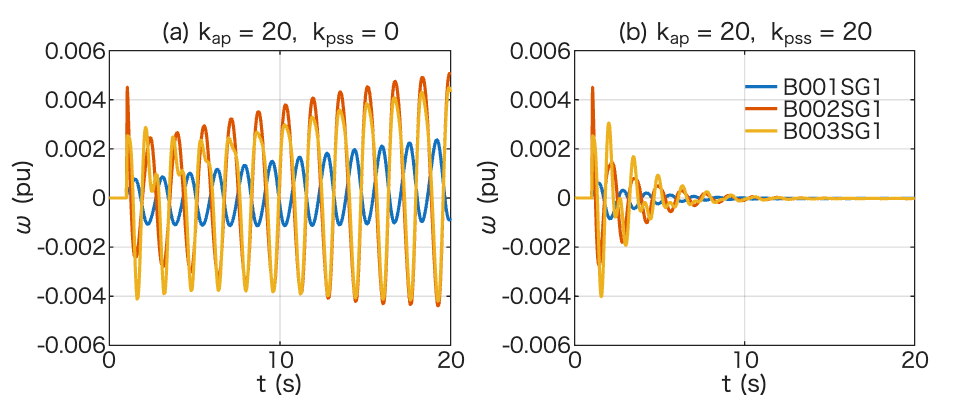

rc_res = cell(1, 2);
for i_case = 1:2
    sc = rc_net9{i_case}.add_scenario("fault", Time=[0, 20]);
    sc.add_fault("B007", [1, 1.05]);
    rc_res{i_case} = rc_net9{i_case}.simulate("fault", Progress="none");
end
sr_title = ["(a) k_{ap} = 20,  k_{pss} = 0", "(b) k_{ap} = 20,  k_{pss} = 20"];
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 2, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 2);
for i_case = 1:2
    a_ax(i_case) = nexttile(tl);
    rc_res{i_case}.plot_trajectory(Quantity="omega", Bus=["B001", "B002", "B003"], Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "t (s)");
    ylabel(a_ax(i_case), "ω (pu)");
    a_ax(i_case).YAxis.Exponent = 0;   % 縦軸の ×10^{-3} を題と重ねない
end
linkaxes(a_ax, "xy");
set(a_ax, FontSize=8, XLim=[0, 20], XGrid="on", YGrid="on", Box="on");
legend(a_ax(1), "off");
set(a_ax(2).Legend, Location="northeast", Box="off", ItemTokenSize=[12, 9]);

**考察:** (a) PSS がないと、発電機 1 が発電機 2・3 に対して揺れる 0.63 Hz のモードが大きくなり続けます。(b) PSS があると、同じモードのダンピング比は約 9%（周波数は約 0.72 Hz）になり、揺れは数秒で収まります。1.3 Hz のモードの減衰も約 3% から約 6% に増えます。線形化で見た固有値の位置が、そのまま時間応答に現れています。PSS は、抑えたいモードへの参加係数の大きい発電機に付けると最もよく効きます（参加係数は Part 5）。

### 大きな系統でも確かめる

同梱の IEEE 68 母線系統から、16 台すべての PSS を外した系統を作ります（AVR は残します）。PSS は AVR の下に付いているので、PSS のタグを指定して外します。母線 1 で 1 秒から 0.05 秒間の三相地絡を起こし、PSS がある場合とない場合で、発電機 16（slack 母線）から見た発電機 9 の回転子の角度を比べます。

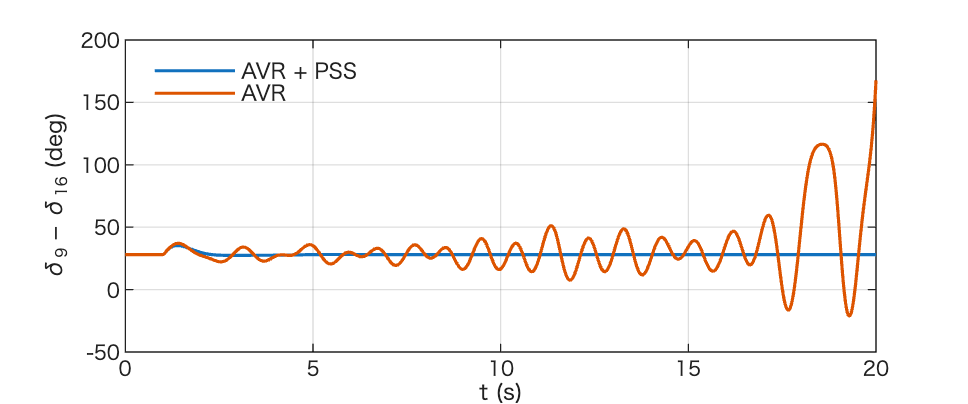

net68N = network.IEEE68bus(LocalController=true);
tab_comp = net68N.get_element_table(Kind="component");
sv_gen68 = tab_comp.Tag(tab_comp.Key == "gen-1axis");    % 16 台の発電機
for s_gen = sv_gen68'
    genN = net68N.get_element(s_gen);
    genN.remove_local_controller(genN.pss.s_tag);
end
net68N.initialize();
a_net68 = {net68, net68N};
a_res68 = cell(1, 3);
for c = 1:2
    sc = a_net68{c}.add_scenario("fault", Time=[0, 20]);
    sc.add_fault("B001", [1, 1.05]);
    a_res68{c} = a_net68{c}.simulate("fault", Progress="none");
end
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
ax = axes(fig, NextPlot="add", XGrid="on", YGrid="on", Box="on");
for c = 1:2
    tab_d = a_res68{c}.get_trajectory("delta", Owner=["B009SG1", "B016SG1"]);
    plot(ax, tab_d.t, rad2deg(tab_d.B009SG1 - tab_d.B016SG1), LineWidth=1.2)
end
xlabel(ax, "t (s)"); ylabel(ax, "δ_9 − δ_{16} (deg)");
legend(ax, ["AVR + PSS", "AVR"], Location="northwest", Box="off");

PSS があると揺れは 2〜3 秒で収まります。PSS がないと、約 1 Hz の揺れが少しずつ大きくなり、20 秒の手前で大きく振れ始めます。固有値は 4 節で LQR と並べて見ます。

## 3. 周波数制御の階層：ガバナと AGC

### 階層

周波数は同期した系統のどこでも同じで、発電が消費より少ないと下がります。これを戻すために、時間の尺度の違う制御が順番に働きます。

- 慣性（最初の数秒）: 制御ではありません。回転子の運動エネルギーが、足りない電力をすぐに補います。

- 一次制御（数秒〜数十秒）: 各ガバナが、周波数のずれに比例して出力を増やします（垂下特性、ガバナフリー運転）。低下は止まりますが、ずれは残ります。

- 二次制御（数十秒〜数分）: 自動発電制御（AGC）が残ったずれを積分し、選んだ発電機の出力の設定を変えて、周波数を定格の値に戻します。

- 三次制御（十数分以上）: 発電機の出力を、最も安くなるように配り直します（経済負荷配分、Part 6）。

### 垂下特性と、残るずれ

一次制御の垂下特性は、調定率 $R$（単位法、数 % 程度）で表します。弁とタービンの動きが落ち着いた後、ガバナは機械入力を次のだけ変えます。


$$\Delta P_\mathrm{mech} = -\frac{P_\mathrm{rate}}{R}\Delta\omega, \qquad \Delta\omega = \frac{\Delta f}{f_0}$$


$P_\mathrm{rate}$ はユニットの定格（系統の基準容量に対する比）、$\Delta\omega$ は単位法の回転速度のずれ（周波数のずれ $\Delta f$ を定格周波数 $f_0$ で割ったもの）です。GUILDA のガバナ `gov-LPT1` では、調定率を % で与えます（`droop` = $100R$、既定 4%）。

出力が変わるのは $\Delta\omega \ne 0$ の間だけなので、一次制御だけでは周波数を完全には戻せません。すべての発電機 $i$ が落ち着いたとき、GUILDA の発電機の動揺方程式 $M_i\dot{\omega}_i = P_{\mathrm{mech},i} - P_{\mathrm{out},i} - D_i\omega_i$ の左辺は 0 で、$\omega_i$ はすべて同じ $\Delta\omega$ になります。3 台を足し合わせると、失った機械入力 $\Delta P_\mathrm{loss}$ と、電気出力の合計の変化 $\Delta P_\mathrm{out}$（負荷と損失の変化）から、残るずれが求まります。


$$\Delta\omega = -\frac{\Delta P_\mathrm{loss} + \Delta P_\mathrm{out}}{\sum_i P_{\mathrm{rate},i}/R + \sum_i D_i}$$


### AGC

AGC は地域要求量（ACE）にもとづいて働きます。隣の地域との連系線で送り出す電力の計画からのずれを $\Delta P_\mathrm{tie}$、その地域の周波数バイアスを $B \gt 0$ とすると、PI 制御で発電機の出力の設定の変化 $\Delta P_\mathrm{ref}$ を決めます。


$$\mathrm{ACE} = \Delta P_\mathrm{tie} + B\Delta f, \qquad \Delta P_\mathrm{ref} = -\left(K_\mathrm{P}\mathrm{ACE} + K_\mathrm{I}\int_0^t \mathrm{ACE}\mathrm{d}\tau\right)$$


ACE が 0 でない限り積分は変わり続けるので、落ち着く先は ACE = 0 だけです。連系線のない 1 つの地域なら、これは $\Delta f = 0$ のことです。GUILDA の AGC `agc-PI` はこの 1 地域の形のグローバル制御器で、制御する発電機の回転速度のずれ $\omega_i$ の重み付きの和 $w$ を積分し、1 つの PI の指令を分けて各発電機の機械入力に加えます。


$$w = \sum_i \beta_i\omega_i, \qquad \dot{\xi} = w, \qquad P_{\mathrm{mech},i} = -\alpha_i\left(k_\mathrm{P}w + k_\mathrm{I}\xi\right)$$


### 3 つの場合を比べる

IEEE 9 母線系統（60 Hz）で、1 秒に発電機 2 の機械入力を 0.1 pu（10 MW）下げ続けます。(a) 周波数の制御なし（同梱の系統のガバナは出力一定の `gov-static`）、(b) 各発電機にガバナ `gov-LPT1`（調定率 4%）、(c) ガバナと AGC `agc-PI`（$\alpha_i = \beta_i = 1$、積分だけ $k_\mathrm{P} = 0$、$k_\mathrm{I} = 2$）の 3 つを、60 秒まで計算します。ガバナの $P_\mathrm{rate}$ には定格のデータがないので、平衡点の機械入力の 1.25 倍（/0.8）とします。

sr_gen9 = ["B001SG1", "B002SG1", "B003SG1"];
rc_netF = cell(1, 3);
rc_resF = cell(1, 3);
for i_case = 1:3
    net = network.IEEE9bus(LocalController=true);
    if i_case >= 2
        for s_gen = sr_gen9
            gen9 = net.get_element(s_gen);
            gen9.add_local_controller("gov-LPT1", parameter=struct(Prate=gen9.rv_Uequilibrium(1) / 0.8));
        end
    end
    if i_case == 3
        agc = net.add_global_controller("agc-PI", sr_gen9, parameter=struct(kP=0, kI=2));
    end
    net.initialize();
    sc = net.add_scenario("loss", Time=[0, 60]);
    sc.add_input("B002SG1", "Pmech", -0.1, [1, 60]);
    rc_netF{i_case} = net;
    rc_resF{i_case} = net.simulate("loss", Progress="none");
end

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1; Pmech_B003SG1_PowerNetworkAGC1 -> Pmech_B003SG1.


3 台の回転速度のずれを、同じ軸で並べます（知識ページの「周波数制御の階層」の図）。

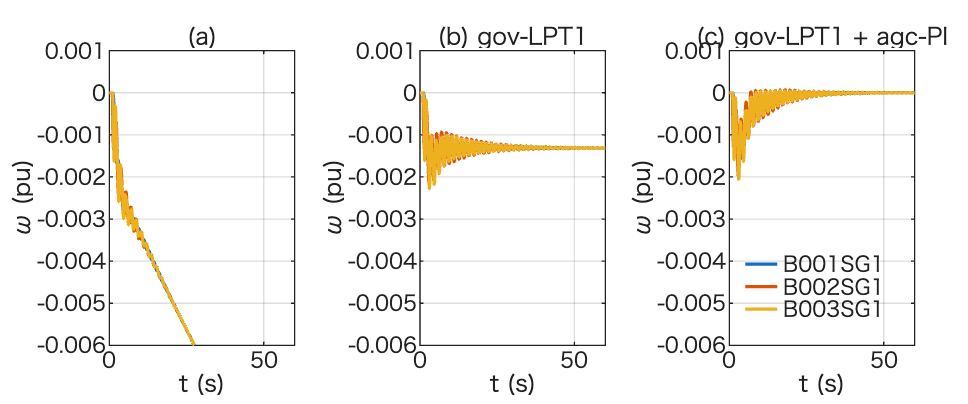

sr_title = ["(a)", "(b) gov-LPT1", "(c) gov-LPT1 + agc-PI"];
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 3, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 3);
for i_case = 1:3
    a_ax(i_case) = nexttile(tl);
    rc_resF{i_case}.plot_trajectory(Quantity="omega", Bus=["B001", "B002", "B003"], Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "t (s)");
    ylabel(a_ax(i_case), "ω (pu)");
    a_ax(i_case).YAxis.Exponent = 0;   % 縦軸の ×10^{-3} を題と重ねない
end
linkaxes(a_ax, "xy");
set(a_ax, FontSize=8, XLim=[0, 60], YLim=[-6e-3, 1e-3], XGrid="on", YGrid="on", Box="on");
legend(a_ax(1), "off");
legend(a_ax(2), "off");
set(a_ax(3).Legend, Location="southeast", Box="off", ItemTokenSize=[12, 9]);

(a) では周波数は下がり続けます（機械入力が一定なので、足りない電力を回転子の運動エネルギーで補い続けるからです）。(b) では低下が止まり、ずれが残ります。(c) では周波数が定格の値に戻ります。

### 残るずれを式で確かめる

(b) の 60 秒での回転速度のずれを、上の式と比べます。$\Delta P_\mathrm{out}$ は 3 台の発電機の電気出力の合計の変化で、`get_trajectory("P")`（母線に機器が注入する電力）から求めます。$P_{\mathrm{rate},i}$ と $D_i$ は `get_parameter` で読みます。

net = rc_netF{2};
rv_Prate = net.get_parameter("dynamics", Key="gov-LPT1").Prate'

rv_Prate =     0.8955    2.0375    1.0625


rv_D = net.get_parameter("dynamics", Key="gen-1axis").D'

rv_D =      2     2     2


tab_P = rc_resF{2}.get_trajectory("P", Bus=["B001", "B002", "B003"]);
dP_out = sum(tab_P{end, 2:end} - tab_P{1, 2:end})     % [pu] 電気出力の合計の変化

dP_out = 0.0387

tab_w = rc_resF{2}.get_trajectory("omega");
r_R = 0.04;                                    % 調定率 4 %
domega_sim = tab_w.B001SG1(end)

domega_sim = -0.0013

domega_lossOnly = -0.1 / (sum(rv_Prate) / r_R)

domega_lossOnly = -0.0010

domega_formula = -(0.1 + dP_out) / (sum(rv_Prate) / r_R + sum(rv_D))

domega_formula = -0.0013

df_mHz = 60 * 1000 * domega_sim

df_mHz = -79.0482

**考察:**

- 失った 0.1 pu だけを使うと、ずれは $-0.1/\sum P_\mathrm{rate}/R \approx -1.0\times 10^{-3}$ pu になりますが、シミュレーションでは約 $-1.3\times 10^{-3}$ pu（約 −79 mHz）残っています。電気出力の合計が約 0.04 pu 増えていて（負荷の消費電力は母線の電圧で変わります）、ガバナはその分も補っているからです。$\Delta P_\mathrm{out}$ と制動 $D_i$ を入れた式の値は、シミュレーションとよく一致します。

- 残るずれは、$\sum P_\mathrm{rate}/R$ に反比例します。調定率 $R$ を小さく（ガバナを強く）すればずれは小さくなりますが、0 にはなりません。ずれを 0 にするには、(c) のように積分が必要です。

- (c) の AGC は積分だけ（$k_\mathrm{P} = 0$）なので、戻り方はゆっくりです。$k_\mathrm{I}$ を大きくすると速く戻りますが、ガバナとの時間の尺度が近づくと、行き過ぎや振動が出やすくなります。三次制御はもっと長い時間で働くので、ここには現れません。

**注意:** `agc-PI` の `alpha`（発電機ごとの指令の分担）と `beta`（周波数のずれの重み）も `parameter` で渡せます。外すときは `net.remove_global_controller(agc.s_tag)` とします。AGC の出力は、ガバナの出力に足し合わされて発電機の `Pmech` に入ります（6 節で確かめます）。

## 4. グローバル制御器と LQR

### LQR の考え方

AVR・PSS・ガバナは、それぞれ 1 台の発電機を見ます。系統の多くの場所を測り、複数の発電機にまとめて働きかける制御器を、GUILDA ではグローバル制御器と呼びます（上の AGC もその 1 つです）。入力と計測が多いと、ゲインを 1 つずつ手で選ぶのは難しくなります。LQR（線形二次レギュレータ）は、線形モデル $\dot{x} = Ax + Bu$ から、すべてのゲインを一度に選びます。状態のずれ $x$ の大きさ（重み $Q$）と、使う入力 $u$ の大きさ（重み $R$）を評価にし、それを最も小さくする状態フィードバック $u = -Kx$ を求めます。


$$J = \int_0^{\infty}\left(x^{\top}Qx + u^{\top}Ru\right)\mathrm{d}t$$


$Q$ は半正定、$R$ は正定の行列です。$Q$ を大きくすると揺れを早く収めることを、$R$ を大きくすると入力を穏やかにすることを求めることになります。最適なゲインは次のとおりです。


$$K = R^{-1}B^{\top}S, \qquad A^{\top}S + SA - SBR^{-1}B^{\top}S + Q = 0$$


$S$ は 2 つ目の式（リッカチ方程式）の半正定の解で、MATLAB では関数 `lqr` で求められます。$(A, B)$ が可安定で $(A, Q^{1/2})$ が可検出なら、閉ループ $\dot{x} = (A - BK)x$ は安定です。弱点は、すべての状態 $x$ を測るか推定しなければならないことと、系統全体のモデルが必要なことです。

### GUILDA の local-LQR

GUILDA の LQR `local-LQR` はローカル制御器で、1 台の発電機を無限大母線につないだモデルからゲインを求め、その発電機のすべての状態を観測して、平衡点 $(x^{\ast}, u^{\ast})$ のまわりで $u = u^{\ast} - K(x - x^{\ast})$ を出力します。2 節の PSS のない IEEE 68 母線系統をもう 1 つ作り、母線 1〜15 の発電機の AVR を LQR に置き換えます（入力は界磁電圧 `Vfield`、$R = 10^{-4}$）。slack 母線の発電機 16 は、PSS のない AVR のままにします。

net68L = network.IEEE68bus(LocalController=true);
for s_gen = sv_gen68'
    genL = net68L.get_element(s_gen);
    genL.remove_local_controller(genL.pss.s_tag);                  % PSS を外す
    if s_gen ~= "B016SG1"
        genL.remove_local_controller(genL.avr.s_tag);              % AVR を外す
        genL.add_local_controller("local-LQR", parameter=struct(Input="Vfield", R=1e-4));
    end
end
net68L.initialize();
gen9L = net68L.get_element("B009SG1");
gen9L.sv_x'       % 観測する状態

ans = 1×3 の string 配列
    "delta"    "omega"    "Eq"


tab_ctrl9 = net68L.get_element_table(Owner="B009SG1");
lqr9 = net68L.get_element(tab_ctrl9.Tag(tab_ctrl9.Key == "local-LQR"));
K9 = lqr9.K       % ゲイン K（Vfield へ）

K9 = 1.0e+03 *

   -0.0112   -4.2692    0.1319


発電機 9 の LQR は、回転子の角度 `delta`・速さ `omega`・内部電圧 `Eq` の 3 つの状態から `Vfield` を決めます。ゲインは `initialize` のときに計算されます。

3 つの系統（AVR + PSS、AVR だけ、LQR）を線形化し、原点付近の固有値を `plot_eigenvalue` で並べます（知識ページの「グローバル制御器と LQR」の図）。不安定な固有値は赤で表示されます。

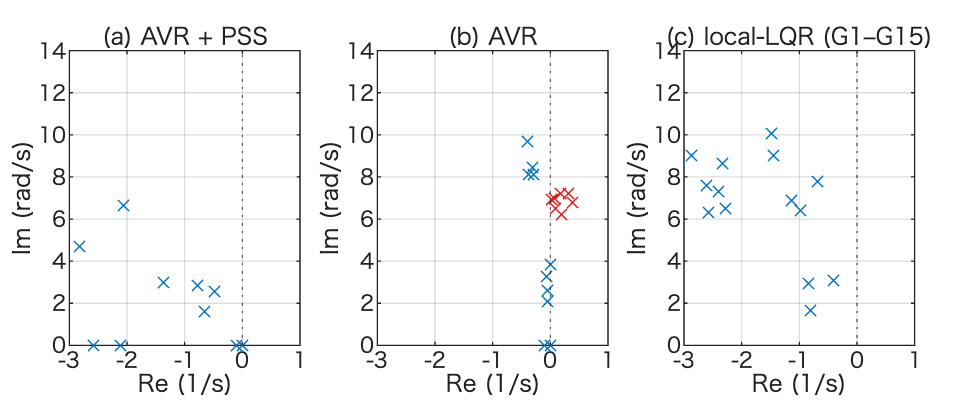

a_net68 = {net68, net68N, net68L};
rc_lin = cell(1, 3);
sr_title = ["(a) AVR + PSS", "(b) AVR", "(c) local-LQR (G1–G15)"];
for i_case = 1:3
    rc_lin{i_case} = a_net68{i_case}.get_sys();
end
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 3, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 3);
for i_case = 1:3
    a_ax(i_case) = nexttile(tl);
    rc_lin{i_case}.plot_eigenvalue(Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "Re (1/s)");
    ylabel(a_ax(i_case), "Im (rad/s)");
end
linkaxes(a_ax, "xy");
set(a_ax, FontSize=8, XLim=[-3, 1], YLim=[0, 14], XGrid="on", YGrid="on", Box="on");

それぞれの系統の、0.1 Hz 以上でいちばん安定でない 3 つのモードです（上から (a)、(b)、(c)）。

for i_case = 1:3
    tab_mode = rc_lin{i_case}.get_mode(MinFrequency=0.1);
    disp(sr_title(i_case)); disp(tab_mode(1:3, :))
end

(a) AVR + PSS
       Eigenvalue       Frequency    DampingRatio      Owner  
    ________________    _________    ____________    _________

    -0.48723+2.579i      0.41045       0.18564       "B015SG1"
    -0.66215+1.6068i     0.25574         0.381       "B014SG1"
    -0.78346+2.8545i     0.45431       0.26468       "B016SG1"

(b) AVR
      Eigenvalue       Frequency    DampingRatio      Owner  
    _______________    _________    ____________    _________

    0.38801+6.7931i      1.0812      -0.057026      "B002SG1"
    0.30709+7.2366i      1.1517      -0.042397      "B003SG1"
    0.19703+6.2079i     0.98802      -0.031723      "B012SG1"

(c) local-LQR (G1–G15)
       Eigenvalue       Frequency    DampingRatio      Owner  
    ________________    _________    ____________    _________

    -0.41231+3.0767i     0.48967       0.13282       "B016SG1"
    -0.69158+7.7829i      1.2387       0.08851       "B001SG1"
    -0.81105+1.6432i     0.26152        0.4426       "B014SG1"



2 節と同じ母線 1 の地絡を、LQR の系統でも計算し、3 つの場合の最初の 10 秒を比べます。

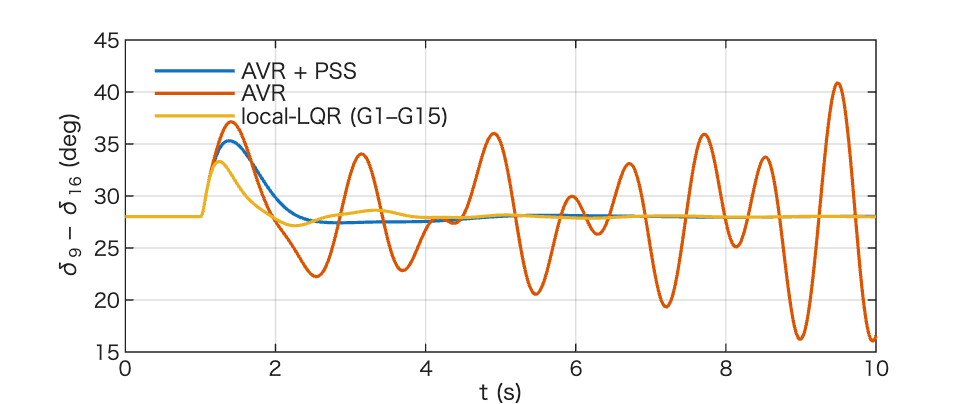

sc = net68L.add_scenario("fault", Time=[0, 20]);
sc.add_fault("B001", [1, 1.05]);
a_res68{3} = net68L.simulate("fault", Progress="none");
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
ax = axes(fig, NextPlot="add", XGrid="on", YGrid="on", Box="on", XLim=[0, 10]);
for c = 1:3
    tab_d = a_res68{c}.get_trajectory("delta", Owner=["B009SG1", "B016SG1"]);
    plot(ax, tab_d.t, rad2deg(tab_d.B009SG1 - tab_d.B016SG1), LineWidth=1.2)
end
xlabel(ax, "t (s)"); ylabel(ax, "δ_9 − δ_{16} (deg)");
legend(ax, ["AVR + PSS", "AVR", "local-LQR (G1–G15)"], Location="northwest", Box="off");

**考察:**

- (b) PSS を外すと、いくつかのモードの実部が正になり（1.08 Hz のモードのダンピング比は約 −6%）、地絡の後の揺れが大きくなっていきます。

- (c) AVR を LQR に置き換えると、すべての固有値が虚軸より左に動き、PSS がなくても揺れは地絡から 3 秒ほどで収まります。各 LQR は 1 台ずつの単純なモデル（無限大母線）から設計されていますが、この例では系統全体を安定にできています。

- ただし、設計に使うモデルは実際の系統と違うので、安定になる保証はありません。この例でも、既定の $R = 1$ のままでは実部が正の固有値が残りました。重みを変えたら、固有値と時間応答で確かめます。

**注意:** `Q`（状態の重み）と `R`（入力の重み）は `parameter` で渡します（既定はどちらも単位行列）。無限大母線の電圧 `V0`（既定 1 pu）が母線の電圧と等しいと設計のモデルが作れずエラーになるので、slack 母線（電圧 1 pu）の発電機 16 を除いています。`local-LQR` は AVR の位置に付き（`s_role` が `"local"`）、AVR と PSS の代わりになります。

## 5. Retrofit 制御：部分のモデルだけで後付けする

### 考え方

実際の電力系統はすでに動いていて、別々の事業者が設計した多くの制御器を持っています。1 台の発電機に新しい制御器を加えるとき、その設計者は系統の残りの部分のモデルを知らず、残りの部分は後で変わるかもしれません。自分の部分のモデルだけで制御器を設計できるか、加えた後も系統全体は安定なままか、という 2 つの問いに答えるのが、石崎・定本・井村・Sandberg・Johansson が提案した Retrofit 制御（後付けの制御）です。

系統を、注目する部分系とその環境（それ以外のすべて）に分けます。Retrofit 制御器は部分系だけに付き、部分系のモデルだけで設計した内部の制御器（たとえば LQR）と、計測から環境の影響を取り除く出力の補正器からなります。元の系統が安定で、内部の制御器が部分系のモデルを単独で安定にするなら、Retrofit 制御器を加えた系統全体も、環境がどうであれ安定です。

### GUILDA の pss-retrofit

GUILDA の `pss-retrofit` は、部分系を 1 台の発電機とした Retrofit 制御による系統安定化装置です。Static の AVR `avr-static` の下に PSS の代わりに付き、その入力 $V_\mathrm{pss}$ を動かします（界磁電圧は $V_\mathrm{field} = V_\mathrm{fd,ref} + V_\mathrm{pss}$）。発電機のすべての状態 $x$ を観測し、入力を平衡点の値 $u^{\ast}$ に固定した発電機のモデルで、その写し $\hat{x}$ を計算し続けます。


$$E\dot{\hat{x}} = f(x, V, u^{\ast}) - A_\mathrm{d}(x - \hat{x}), \qquad V_\mathrm{pss} = -K(x - \hat{x})$$


$E\dot{x} = f(x, V, u)$ は母線電圧 $V$ と入力 $u = (P_\mathrm{mech}, V_\mathrm{field})$ を持つ発電機のモデル、$A_\mathrm{d} = \partial f/\partial x$ と $B = \partial f/\partial V_\mathrm{field}$ は平衡点での値、$K$ は発電機だけのモデルから求めた LQR のゲイン（$E^{-1}A_\mathrm{d}$、$E^{-1}B$、$Q$、$R$ から `lqr` で計算）です。写し $\hat{x}$ が出力の補正器の役をします。$f$ は $V_\mathrm{field}$ について線形なので、誤差 $e = x - \hat{x}$ は厳密に次の式に従います。


$$E\dot{e} = (A_\mathrm{d} - BK)e$$


したがって誤差は、系統の残りがどう動いても減衰し、線形化した系統の固有値は、制御器がないときの固有値と $E^{-1}(A_\mathrm{d} - BK)$ の固有値を合わせたものになります。平衡点では $\hat{x} = x$、$V_\mathrm{pss} = 0$ なので、付けても運転点は動きません。

### 付けて比べる

IEEE 9 母線系統の発電機 2 の AVR（と PSS）を外して `avr-static` にした系統 (a) と、その下にさらに `pss-retrofit`（$R = 0.01$、$Q$ は単位行列）を付けた系統 (b) を作ります。どちらも、時刻 0 に発電機 2 の内部電圧 $E_q$ を 0.1 pu ずらした応答を 10 秒まで計算します。

rc_resR = cell(1, 2);
rc_linR = cell(1, 2);
for i_case = 1:2
    net = network.IEEE9bus(LocalController=true);
    gen2 = net.get_element("B002SG1");
    gen2.remove_local_controller(gen2.avr.s_tag, RemoveNested=true);
    gen2.add_local_controller("avr-static");
    if i_case == 2
        rf = gen2.add_local_controller("pss-retrofit", parameter=struct(R=0.01));
    end
    net.initialize();
    rc_linR{i_case} = net.get_sys();
    sc = net.add_scenario("kick", Time=[0, 10]);
    sc.add_offset(gen2.s_tag, "Eq", 0.1, 0);
    rc_resR{i_case} = net.simulate("kick", Progress="none");
end
netR = net;    % (b) の系統（6 節でも使う）
gen2.disp_tree


 B002SG1 @component.generator.one_axis
   ┣━━ B002SG1CA1 @controller.avr.Static
   ┃     ┗━━ B002SG1CP1 @controller.pss.Retrofit
   ┗━━ B002SG1CG1 @controller.governor.Static




tab_ctrlR = netR.get_element_table(Owner="B002SG1");
tab_ctrlR(:, ["Key", "Role", "State", "Input", "Output"])

ans = 3×5 table
                       Key             Role                   State                       Input            Output 
                  ______________    __________    ______________________________    __________________    ________

    B002SG1CA1    "avr-static"      "avr"         ""                                "Vfd_ref, Vpss"       "Vfield"
    B002SG1CP1    "pss-retrofit"    "pss"         "hat_delta, hat_omega, hat_Eq"    "delta, omega, Eq"    "Vpss"  
    B002SG1CG1    "gov-static"      "governor"    ""                                "Pmech_ref"           "Pmech" 


K_rf = rf.K       % ゲイン K（Vpss へ）

K_rf =     4.5779 -176.7433   17.7457


Retrofit 制御器（`CP1`）は、発電機の 3 つの状態を観測し、その写し `hat_delta`・`hat_omega`・`hat_Eq` を状態に持ちます。3 台の回転速度のずれを描きます（知識ページの「Retrofit 制御」の図）。

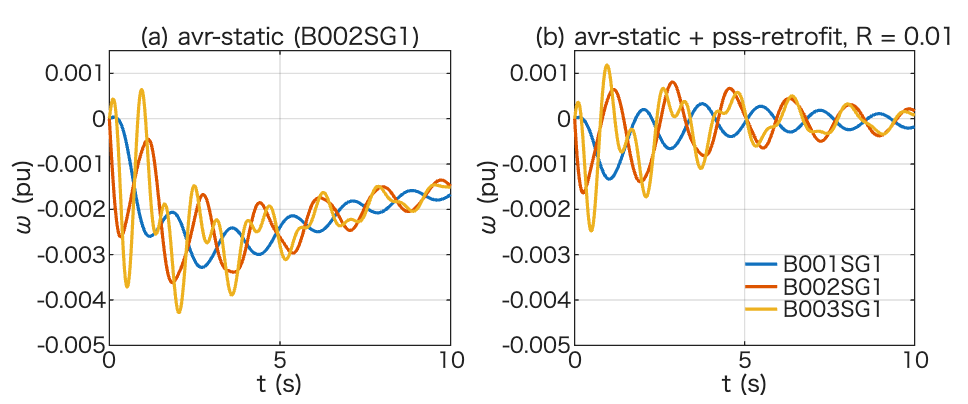

sr_title = ["(a) avr-static (B002SG1)", "(b) avr-static + pss-retrofit, R = 0.01"];
fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 2, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 2);
for i_case = 1:2
    a_ax(i_case) = nexttile(tl);
    rc_resR{i_case}.plot_trajectory(Quantity="omega", Bus=["B001", "B002", "B003"], Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "t (s)");
    ylabel(a_ax(i_case), "ω (pu)");
    a_ax(i_case).YAxis.Exponent = 0;   % 縦軸の ×10^{-3} を題と重ねない
end
linkaxes(a_ax, "xy");
set(a_ax, FontSize=8, XLim=[0, 10], XGrid="on", YGrid="on", Box="on");
legend(a_ax(1), "off");
set(a_ax(2).Legend, Location="southeast", Box="off", ItemTokenSize=[12, 9]);

rv_intOmega = zeros(1, 2);       % 発電機 2 の ∫|ω| dt（(a)、(b)）
for i_case = 1:2
    tab_w = rc_resR{i_case}.get_trajectory("omega", Owner="B002SG1");
    rv_intOmega(i_case) = trapz(tab_w.t, abs(tab_w.B002SG1));
end
rv_intOmega

rv_intOmega =     0.0214    0.0046


**考察:** (a) Static の AVR だけでは、回転速度のずれは何秒も 0 より下にとどまります。(b) Retrofit 制御器があると、ずれは 0 のまわりにとどまり、早く収まります。発電機 2 の $|\omega|$ の 10 秒間の積分は、約 0.021 から約 0.005 に減ります。

### 固有値が分かれることを確かめる

上の式のとおり、(b) の線形化した系統の固有値が、(a) の固有値と $E^{-1}(A_\mathrm{d} - BK)$ の固有値を合わせたものになっているかを確かめます。設計に使った発電機だけのモデルは `rf.sys_design`（状態空間モデル、$A = E^{-1}A_\mathrm{d}$、$B = E^{-1}B$）にあります。

cv_err = eig(rf.sys_design.A - rf.sys_design.B * rf.K)          % 誤差の固有値

cv_err =   -0.9830 + 9.1852i
  -0.9830 - 9.1852i
  -2.3590 + 0.0000i


cv_a = rc_linR{1}.get_mode().Eigenvalue;     % (a) のモード（複素共役の対は Im > 0 の 1 つ）
cv_b = rc_linR{2}.get_mode().Eigenvalue;     % (b) のモード
cv_ab = sort([cv_a; cv_err(imag(cv_err) >= 0)]);
max_mismatch = max(abs(sort(cv_b) - cv_ab))

max_mismatch = 2.5437e-12

**考察:** 2 つの集合の差はとても小さく（数値計算の誤差の程度）、固有値は分かれています。Retrofit 制御器は、元の系統の固有値を 1 つも動かさず、誤差の固有値（すべて左半平面）を加えるだけです。だから、元の系統が安定なら、付けた後も必ず安定です。

**注意:**

- 既定の重み（$Q$ は単位行列、$R = 1$）では効きがとても小さく、IEEE 9 母線系統の発電機 2 では極の対がほとんど動きません。$R$ を 0.01 程度に小さくして使います。

- 保証されるのは誤差 $e$ の減衰です。遠くの母線の地絡のように電圧 $V$ を通して入る外乱では、$x$ と $\hat{x}$ が同じように動くので $e$ は 0 のままで、制御器は何もしません。発電機全体の揺れ（$x = \hat{x} + e$）が小さくなるとは限りません。

- `Pmech` は観測しないので、写しは平衡点の値を使います。既定の Static のガバナでは厳密ですが、`gov-LPT1` のようなガバナや AGC があると近似になります。

- 付けられるのは `avr-static` の下だけです。`avr-ST1` や `avr-DC1` の下に付けようとするとエラーになり、発電機は元のままです。GUILDA の `local-LQR` も 1 台の発電機からゲインを求めますが、補正器を持たないので Retrofit 制御器ではなく、上の性質も持ちません。

## 6. 自作するときの考え方：観測 → 計算 → 入力

ここまでに使った制御器を、「何を観測するか（入力 `sv_u`）」「何を状態に持って計算するか（状態 `sv_x`）」「どの入力を動かすか（出力 `sv_y`）」で並べます。

sv_col = ["Key", "Role", "Input", "State", "Output"];    % ① 観測する、② 状態、③ 動かす
tab_F = rc_netF{3}.get_element_table(Kind=["local", "global"]);
tab_F(startsWith(tab_F.Tag, "B002") | tab_F.Kind == "global", sv_col)    % AVR・PSS・ガバナ・AGC（3 節 (c)）

ans = 4×5 table
                           Key           Role               Input                    State             Output 
                        __________    __________    _____________________    _____________________    ________

    B002SG1CA1          "avr-ST1"     "avr"         "Vref, Vpss, Ifield"     "Vtr, Vap, Vst"          "Vfield"
    B002SG1CP2          "pss-PSS1"    "pss"         "omega"                  "xiWS, xi1, xi2"         "Vpss"  
    B002SG1CG3          "gov-LPT1"    "governor"    "omega, Pref, Plimit"    "Pgov, Psv, Pch, Prh"    "Pmech" 
    PowerNetworkAGC1    "agc-PI"      "agc"         "omega"                  "xi"                     "Pmech" 


tab_ctrl9(:, sv_col)     % LQR（4 節）

ans = 2×5 table
                      Key            Role             Input           State     Output 
                  ____________    __________    __________________    _____    ________

    B009SG1CL1    "local-LQR"     "local"       "delta, omega, Eq"     ""      "Vfield"
    B009SG1CG1    "gov-static"    "governor"    "Pmech_ref"            ""      "Pmech" 


tab_ctrlR(:, sv_col)     % Static の AVR と Retrofit（5 節）

ans = 3×5 table
                       Key             Role             Input                       State                  Output 
                  ______________    __________    __________________    ______________________________    ________

    B002SG1CA1    "avr-static"      "avr"         "Vfd_ref, Vpss"       ""                                "Vfield"
    B002SG1CP1    "pss-retrofit"    "pss"         "delta, omega, Eq"    "hat_delta, hat_omega, hat_Eq"    "Vpss"  
    B002SG1CG1    "gov-static"      "governor"    "Pmech_ref"           ""                                "Pmech" 


どの制御器も同じ形です。LQR はクラスの中では入力を `Xall`（発電機のすべての状態を表す予約された名前）と書いていて、発電機に付けたときに `delta`・`omega`・`Eq` に置き換わります。LQR は状態を持たず、観測した値から出力だけを計算します。Retrofit も発電機のすべての状態を観測し、その写しを状態に持って、PSS と同じ AVR の入力 `Vpss` を動かします。AGC は 3 台の発電機それぞれの `omega` を観測し、それぞれの `Pmech` を動かします。3 節 (c) の系統で、発電機 2 のどの入力がどの出力で動いているかを `disp_connection` で表示します。

rc_netF{3}.disp_connection(Owner="B002SG1")


 Signal connections of PowerNetwork @network.IEEE9bus
 <: input port, o: held object; several sources are summed (━┳); Kind: local, global, observe
 Bus voltages that controllers read directly are not connections and are not listed.

 B002 @Bus
   ┗━━o B002SG1 @component.generator.one_axis
         ┣━━< Pmech  ━┳ output Pmech of B002SG1CG3        [local]
         ┃            ┗ output Pmech of PowerNetworkAGC1  [global]
         ┣━━< Vfield ━━ output Vfield of B002SG1CA1       [local]
         ┣━━o B002SG1CA1 @controller.avr.AVR_ST1
         ┃     ┣━━< Vpss   ━━ output Vpss of B002SG1CP2  [local]
         ┃     ┣━━< Ifield ━━ output Ifield of B002SG1   [observe]
         ┃     ┗━━o B002SG1CP2 @controller.pss.PSS1
         ┃           ┗━━< omega ━━ out

発電機の `Pmech` には、ガバナの出力（`local`）と AGC の出力（`global`）が足し合わされて入っています。ガバナと AGC は発電機の出力 `omega` を、AVR は `Ifield` を観測しています（`observe`）。

制御器を自作するときは、ローカル制御器なら `LocalController`、グローバル制御器なら `GlobalController` を継承したクラスを作ります。手本にできる同梱の制御器のクラスは、`GUILDA.dictionary` で一覧にできます（Key のあるものが、`add_local_controller` で付けられるクラスです）。サブクラスが必ず定義するメソッド（抽象メソッド）は、その下のとおりです（上がローカル制御器、下がグローバル制御器）。

GUILDA.dictionary("LocalController");

 
Search for 'LocalController' class
  Link   Type        Key           class tree
  [doc]  -:Abstract                LocalController
  [doc]  o:Concrete  avr-static      ┣━━ controller.avr.Static
  [doc]  -:Abstract                  ┣━━ controller.avr.abstract
  [doc]  o:Concrete  avr-DC1         ┃   ┣━━ controller.avr.AVR_DC1
  [doc]  o:Concrete  avr-ST1         ┃   ┗━━ <a href=

mcL = ?LocalController;
mcG = ?GlobalController;
sv_L = string({mcL.MethodList([mcL.MethodList.Abstract]).Name})'

sv_L = 6×1 の string 配列
    "get_equilibrium"
    "Jacobi_Y"
    "Jacobi_dx"
    "fcn_Mass"
    "fcn_y"
    "fcn_dx"


sv_G = string({mcG.MethodList([mcG.MethodList.Abstract]).Name})'

sv_G = 4×1 の string 配列
    "get_equilibrium"
    "fcn_Mass"
    "fcn_y"
    "fcn_dx"


`fcn_dx`・`fcn_y`・`fcn_Mass` が状態方程式と出力（② 計算する）、`get_equilibrium` が平衡点での状態と入力、`Jacobi_dx`・`Jacobi_Y` が線形化に使う微分です（`GlobalController` では抽象メソッドに入っていませんが、同梱の AGC は定義しています）。これに、観測する信号の名前 `sv_u`（①）、動かす入力の名前 `sv_y`（③）、状態の名前 `sv_x`、Key（`key`）と役割（`s_role`）を定数のプロパティとして書きます。

自作の制御器では、この 3 つに続いて、次のことも決めておきます。

- 平衡点: 系統が落ち着いているとき、制御器の状態と出力はいくつか。潮流計算で決めた運転点から系統を動かしてはいけません（グローバル制御器の出力は平衡点で 0 にします）。

- 時間の尺度: 速い制御（電圧、揺れ）か、遅い制御（周波数の回復）か。時間の尺度が大きく違う制御どうしは、干渉しにくくなります。

- 確かめ方: 線形モデルで固有値が左へ動くか（4 節）、時間シミュレーションで事故に耐えるか（2 節）。GUILDA では両方が同じ制御器のモデルを使うので、1 つの制御器のクラスを両方の方法で確かめられます。

**注意:** 書き方の手本には、同梱の制御器のクラスが使えます（たとえば `edit controller.pss.PSS1`、`edit controller.agc.broadcast_PI_AGC`）。`doc LocalController` と `doc GlobalController` に、名前でつなぐ規則と予約された名前（`Xall`、`Yall`）の説明があります。新しいクラスを作ったら `GUILDA.update_keymap` を実行すると、その Key を `add_local_controller` や `add_global_controller` で使えるようになります。

## まとめ

- 制御器は測り、目標と比べ、入力を変えます（フィードバック）。線形モデルでは、よい制御器は固有値を左へ動かします。

- AVR のゲインを上げると、IEEE 9 母線系統の 0.63 Hz のモードのダンピング比が約 −2% になり、揺れが大きくなりました。PSS は速さにもとづく信号を AVR に加えて制動トルクをつくり、同じモードを約 9% にしました。

- ガバナは周波数の低下を止めますが、ずれ $\Delta\omega = -(\Delta P_\mathrm{loss} + \Delta P_\mathrm{out})/(\sum P_\mathrm{rate}/R + \sum D)$ が残ります。AGC（グローバル制御器）は残ったずれを積分して、周波数を定格に戻します。

- LQR は評価関数とリッカチ方程式からすべてのゲインを選びます。IEEE 68 母線系統で AVR を local-LQR に置き換えると、PSS がなくても系統は安定になりました。

- Retrofit 制御は、部分のモデルだけで設計した制御器を、元の固有値を動かさずに加えます（固有値が分かれることを数値で確かめました）。

- どの制御器も「観測 → 計算 → 入力」です。GUILDA では、`LocalController` や `GlobalController` の入力の名前、状態とモデルの関数、出力の名前がそれに当たります。

## 講義のおわりに

これで全 9 Part の講義は終わりです。系統を作り（Part 1）、潮流を求め（Part 2）、時間応答（Part 3・4）と線形モデル（Part 5）で動きを調べ、運転点を選び（Part 6・7）、最後に制御器で動きを変えました。講義全体の地図は、知識ページ [Part 0: 導入](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part0-introduction.html","-browser")) で見直せます。ほかの系統や機器のモデルでも、同じ手順で試してみてください。

[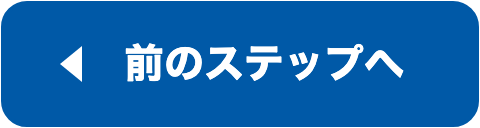](matlab:open('Part7_ContinuationPowerFlow.mlx'))　　[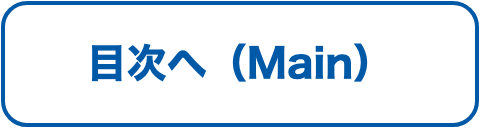](matlab:open('Main.mlx'))